IAE = 113.0379			P = 1		I = 0		D = 0
IAE = 104.0121			P = 2.4284		I = 2.437		D = 0.69775
IAE = 251.0064			P = 20.7293		I = 2.6615		D = 1.3709

                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0               3             104             156        0
IAE = 475.34			P = 35.7284		I = 0		D = 0
IAE = 114.9914			P = 7.4859		I = 3.1437		D = 0
IAE = 276.0618			P = 40		I = 4		D = 3.0409
    1               6             104           288.8        0
IAE = 261.921			P = 31.746		I = 0.17183		D = 1.3629
IAE = 134.1679			P = 1		I = 2.1653		D = 0.53151
IAE = 255.7513			P = 1		I = 1.0199		D = 1.9562
    2               9             104           217.3        1
IAE = 261.9601			P = 24.7385		I = 0.26424		D = 2.0058
IAE = 226.8553			P = 3.9823		I = 1.9437		D = 1.3913
IAE = 146.0467			P = 21.0832		I = 0		D = 0
    3              12             104           211.6        2
IAE = 148.3713			P = 1		I = 4		D = 0
IAE = 117

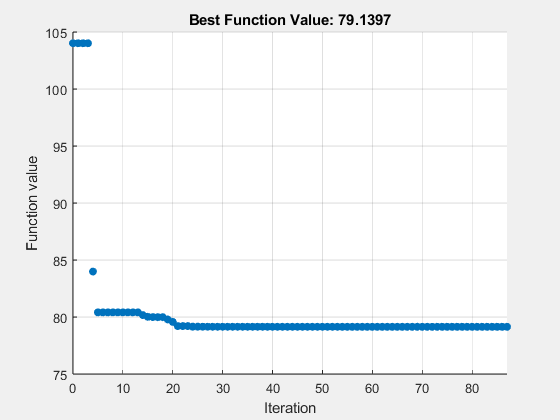

% Set nondefault solver options
options3 = optimoptions("particleswarm","InitialPoints",K_start,...
    "InertiaRange",Inertia_range,"SelfAdjustmentWeight",2,...
    "SocialAdjustmentWeight",2,"MaxIterations",100,"SwarmSize",5,"Display",...
    "iter","PlotFcn","pswplotbestf");

% Solve
[sol,obj] = particleswarm(@tunning,numvar,lower_bounds,...
    upper_bounds,options3);


% Clear variables
clearvars options3